%Remove any variables in memory space
clear all; close all;

img =imread('blurry.jpg')

img = 1080×1440×3 uint8 array
img(:,:,1) =

    51    52    53    54    54    54    54    53    53    53    53    53    53    53    53    53    52    52    52    52    52    52    52    52    56    55    53    52    52    53    55    56    55    55    55    55    55    55    55    55    55    54    53    53    55    55    54    53    53    53    53    53    53    53    53    53    52    52    52    52    52    52    52    52    55    54    54    53    53    54    54    55    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    54    53    52    52    53    54    56    57    57    56    56    55    55    56    56    57    58    59    59    60    60    59    59    56    55    54    54    54    54    54    54    54    54    54    54    55    55    56    56    56    59    59    59    59    59    59    59    59    59    58    58    57    57    58    58    59    59    59    59    58    58    57    57    56    61    60    60    59    59    60    60  

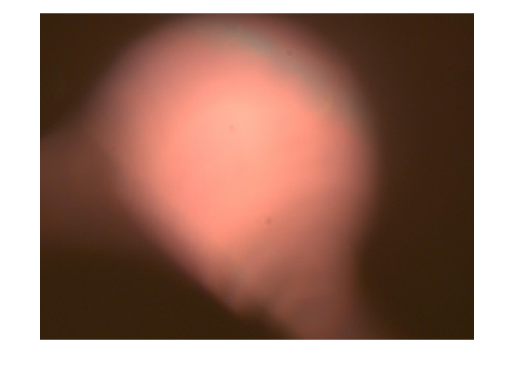

figure('Name','Original Image'); imshow(img);

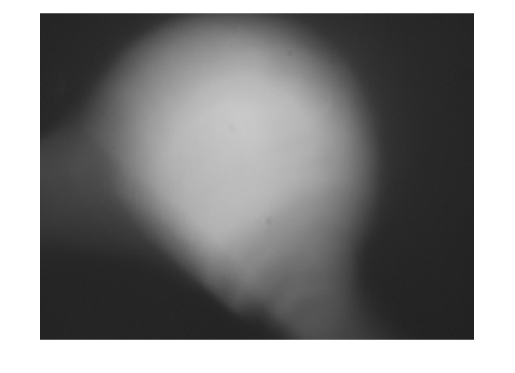


% Now let's convert into grayscale image
gray_img=rgb2gray(img);
figure('Name','Gray Scale Image'); imshow(gray_img);

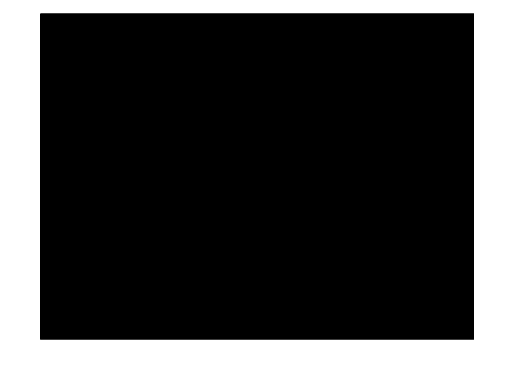


%Get Fourier Transform of an image
F = fft2(gray_img);
figure('Name','Fourier transform of an image'); imshow(abs(F), []);

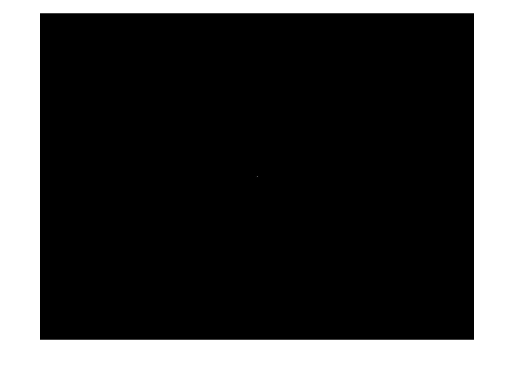


%Get the centered spectrum
Fsh = fftshift(F);
figure('Name','Centered fourier transform of Image');  imshow(abs(Fsh), []);

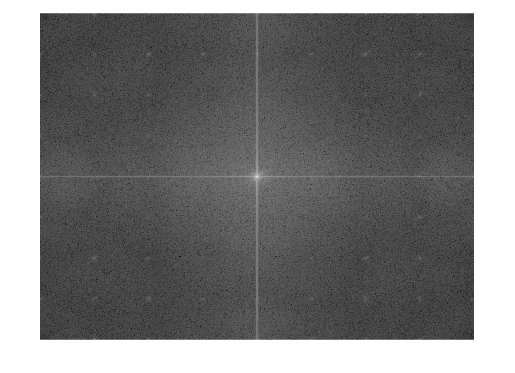


%apply log transform
log_img = log(1+abs(Fsh));
figure('Name','Log fourier transform of Image'); imshow(log_img,[]);



size(log_img)

ans =         1080        1440



Y = abs(log_img)

Y =           1.09861228866811          4.10594895961159          5.16971808106981          4.39907855595053          4.76803594718712          4.81973872284702          4.67513748850056          4.02891578336013          3.55737604414644          4.49402696962292          4.29974155347606          4.49418000162019          4.55745593288752          5.28997386509586          4.50227080721533          4.93519075014197           4.6402343338568          4.67659384969685          3.76623238897175          4.15947398296254          4.30761203309385          3.75848511150077          3.78397445465471          4.39278544110916          4.89410690846741          4.96402780696679          5.24850011795734          4.82220446748402          4.69412406633406          4.28891903128963          3.89198484208227          4.66124664218768          4.82123524152538          4.87839257944823          5.13610701465913           4.8101306911222          3.69463650344267          4.98387790672666        

sum = 0

sum =      0


for i = 1:10
    for j = 1:10
        sum = sum + double(log_img(535 + i, 715 + j))
    end
end

sum =           11.6572291874032


sum =           23.5409227473156


sum =           36.3917966209488


sum =           49.7266273669156


sum =             62.45577455233


sum =           75.9469060191906


sum =           89.6856639982442


sum =           103.179700670771


sum =           116.415530635634


sum =           129.216828393501


sum =           142.402219606029


sum =            154.31560686392


sum =           167.379217571557


sum =           181.049440524253


sum =            194.85791305182


sum =           208.699086360211


sum =           222.520674299306


sum =           236.318336144137


sum =           249.837238622094


sum =           263.199078518714


sum =           276.211040154854


sum =           289.716220169836


sum =           303.002449706072


sum =           316.813508960077


sum =           330.128495485585


sum =           344.261857742711


sum =           358.549723246164


sum =           373.223233431532


sum =           387.658435474088


sum =            401.40314239702


sum =           414.012144876799


sum =           427.610593288611


sum =           440.734266251079


sum =           455.598971494235


sum =           470.511044813816


sum =           485.604355893383


sum =           501.337127851988


sum =           516.885756848909


sum =           531.254664265007


sum =           545.619092690852


sum =           559.206841962579


sum =           572.788877439338


sum =           583.521538855192


sum =           598.483305964329


sum =           614.803243968063


sum =           631.992352842555


sum =           648.564063094309


sum =            662.74653750686


sum =           677.881435221827


sum =           691.563898584395


sum =           705.828897346761


sum =           719.765967731807


sum =           734.808013955977


sum =           750.375236147392


sum =           768.003390972556


sum =           786.740668692195


sum =           804.368823517359


sum =           819.936045708774


sum =           834.978091932944


sum =            848.91516231799


sum =           862.188615964172


sum =            875.87107932674


sum =           891.005977041707


sum =           905.188451454258


sum =           921.760161706012


sum =           938.949270580504


sum =           955.269208584238


sum =           970.230975693375


sum =           980.963637109229


sum =           994.545672585988


sum =           1008.00410099373


sum =           1022.36852941958


sum =           1036.73743683567


sum =           1052.28606583259


sum =            1068.0188377912


sum =           1083.11214887077


sum =           1098.02422219035


sum =            1112.8889274335


sum =           1126.01260039597


sum =           1139.61104880778


sum =           1152.83028260993


sum =           1166.57498953286


sum =           1181.01019157542


sum =           1195.68370176079


sum =           1209.97156726424


sum =           1224.10492952137


sum =           1237.41991604687


sum =           1251.23097530088


sum =           1264.51720483712


sum =            1278.0223848521


sum =           1290.81119650409


sum =           1304.17303640071


sum =           1317.69193887867


sum =            1331.4896007235


sum =           1345.31118866259


sum =           1359.15236197098


sum =           1372.96083449855


sum =           1386.63105745125


sum =           1399.69466815888


sum =           1411.60805541678



avg = double(sum/100)

avg =           14.1160805541678



mappedVal = maptorange(avg, [0,20], [0,1000])

mappedVal =           705.804027708388
